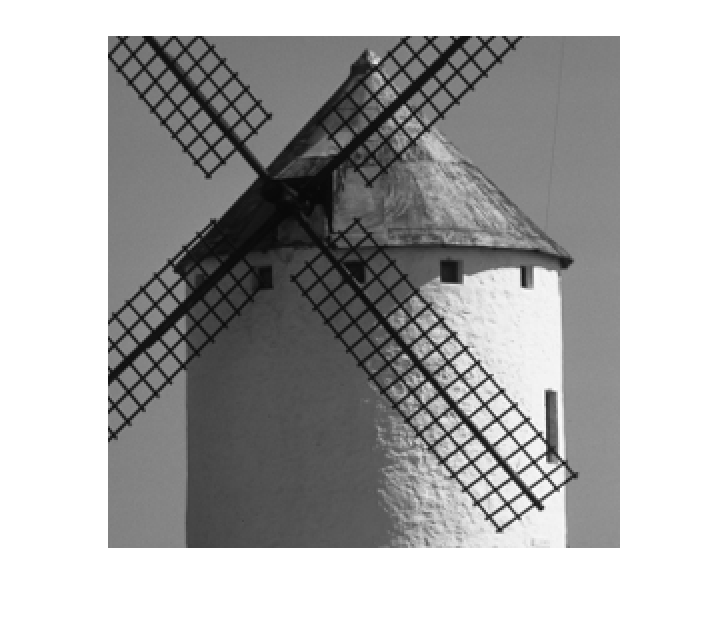

image = imread('kvarn.tif');
image = im2double(image);

### 1 Tröskelrastrering

**1.1**

image_troskrast = image>0.5

image_troskrast = 512×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

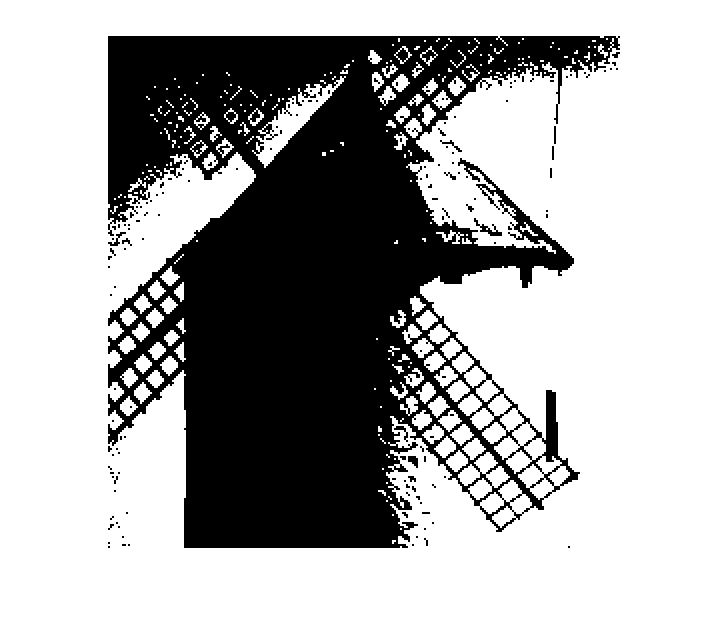

imshow(image_troskrast);

imwrite(image_troskrast,'b11.tif','Resolution', 150);

**1.2-1.3**

load('troskelmatriser.mat');
tr1 = tr1/19; % 6x6
tr2 = tr2/33; % 8x8
tr3 = tr3/33;

b12_tr1 = troskel(image,tr1);
b12_tr2 = troskel(image,tr2);
b13_tr3 = troskel(image,tr3);

imwrite(b12_tr1,'b12_tr1.tif','Resolution', 150);
imwrite(b12_tr2,'b12_tr2.tif','Resolution', 150);
imwrite(b13_tr3,'b13.tif','Resolution', 150);

%imshow(b12_tr1);
%imshow(b12_tr2);

**1.4**

Linj = [1 2 3 4;
       5 6 7 8;
       9 10 11 12;
       13 14 15 16;];
Spi = [1 2 3 4;
       12 13 14 5;
       11 16 15 6;
       10 9 8 7;];
   
Linj = Linj/17;
Spi = Spi/17;

b14_spi = troskel(image,Spi);
b14_linj = troskel(image,Linj);

imwrite(b14_spi,'b14_spi.tif','Resolution', 150);
imwrite(b14_linj,'b14_linj.tif','Resolution', 150);

### 2 Tabellrastrering

**2.1**

image_tabellrast = tabellrast(image);
imwrite(image_tabellrast,'b21.tif','Resolution', 150);

**2.2**

image_tabellrast2 = tabellrast2(image);
imwrite(image_tabellrast2,'b22.tif','Resolution', 150);

**2.3**

image_tabellrast3 = tabellrast3(image);
imwrite(image_tabellrast3,'b23.tif','Resolution', 150);

### 3. Felspridning (error diffusion)

**3.1**

filt = [0 0 7;
        3 5 1]/16;
    
FS_image = errordif(image, filt); %Floyd Steinberg
imwrite(FS_image,'b31.tif','Resolution', 150);

**3.2-3.3**

filt = [0 0 0 7 5;
        3 5 7 5 3;
        1 3 5 3 1]/48;

JJN_image = errordif(image, filt);
imwrite(JJN_image,'b32.tif','Resolution', 150);

**3.4-3.5**

filt1 = [0 0 1;
         0 0 0]; %Sprider felet åt höger med vikten 1

filt2 = [0 0 0.3;
         0 0.7 0]; %Sprider felet åt höger med vikten 0.3 och ner med vikten 0.7

filt1_image = errordif(image, filt1);
filt2_image = errordif(image, filt2);

imwrite(filt1_image,'b341.tif','Resolution', 150);
imwrite(filt2_image,'b342.tif','Resolution', 150);

**3.6**

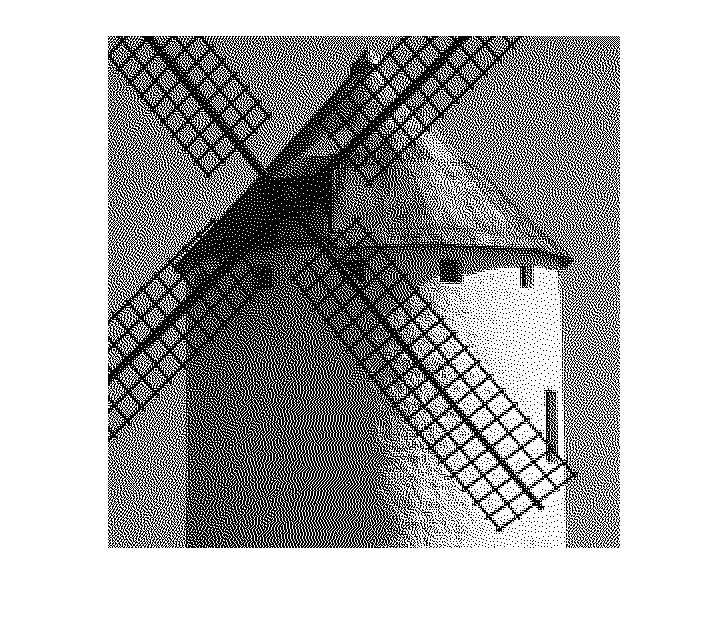

x = rand([512,512]);
k = 0.01;
x = (x-0.5)*k;

imagex = image+x;

FS_image2 = errordif(imagex, filt); %Floyd Steinberg
imshow(FS_image2);

imwrite(FS_image2,'b36.tif','Resolution', 150);

### 4. Iterativ rastrering

imcdp_image = imcdp(image);

imcdp
----------
here13
here14
here14
9% done
----
17% done
----
26% done
----
34% done
----
43% done
----
52% done
----
60% done
----
69% done
----
78% done
----
86% done
----
95% done
----
here9
here15
here8
here10
here6
here17
here7
here5
here4
here18
here16
here11
here3
here2
here12
here1


imwrite(imcdp_image,'b40.tif','Resolution', 150);

### 5. Objektiva kvalitetsmått

**5.1**

x = image-image_troskrast;
mysnr(image, x) %b11

ans = 2.5915


y = image-FS_image;
mysnr(image, y) %b31

ans = 0.8801


z = image-imcdp_image;
mysnr(image, z) %b401

ans = 0.8067

**5.2**

snr_filter(image, x) %b11

ans = 2.9988

snr_filter(image, y) %b31

ans = 13.9621

snr_filter(image, z) %b40

ans = 12.0004

**5.3**

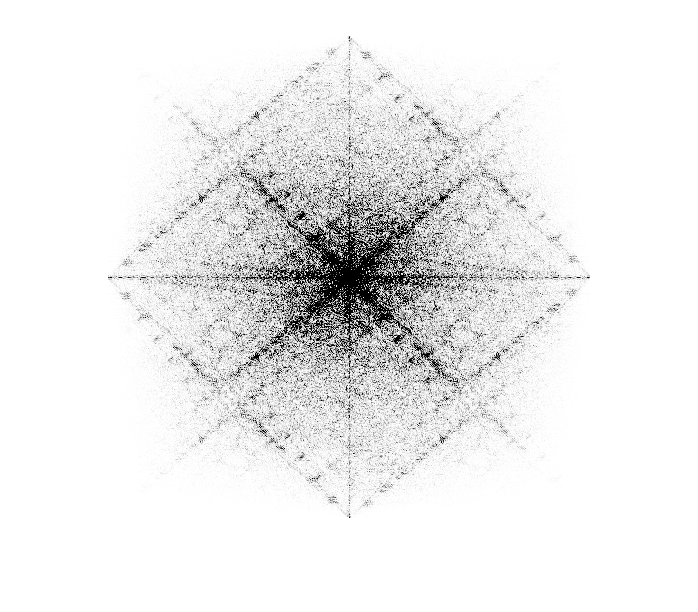

QNS_tr = QNS(image, image_troskrast);

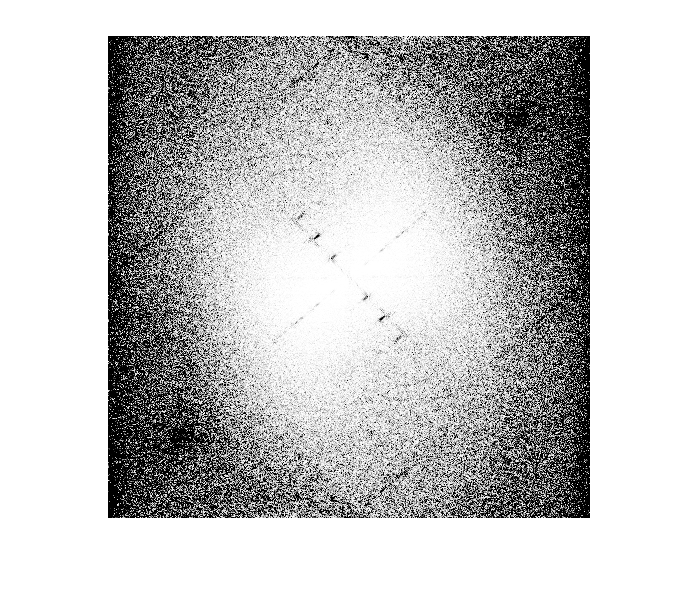

QNS_fs = QNS(image, FS_image);

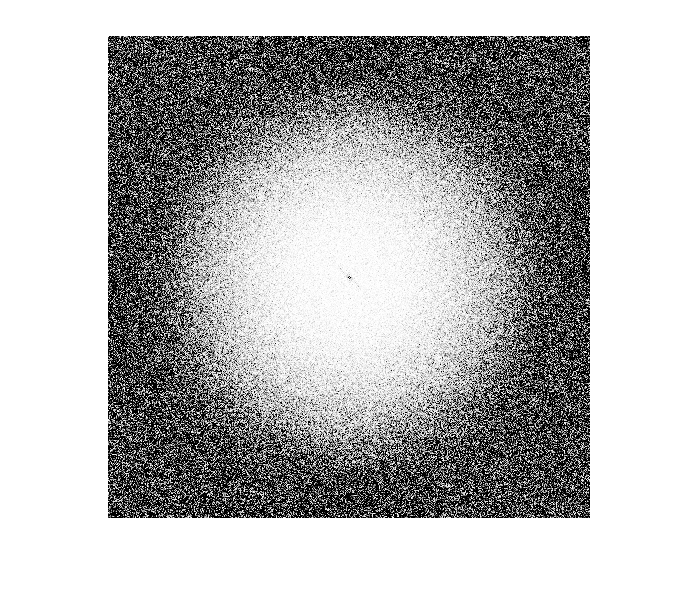

QNS_imcdp = QNS(image, imcdp_image);


imwrite(QNS_tr,'b53a.tif','Resolution', 150);
imwrite(QNS_fs,'b53b.tif','Resolution', 150);
imwrite(QNS_imcdp,'b53c.tif','Resolution', 150);

## Del 3

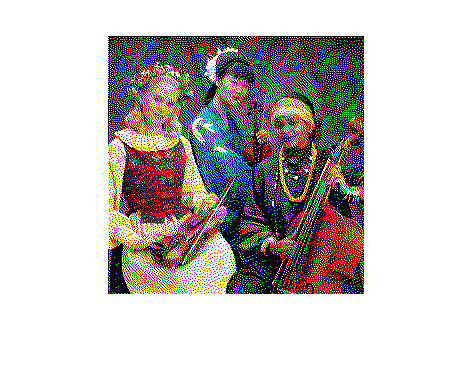

image_m = imread('musicians.tif');
image_m = im2double(image_m);

image_b = imread('butterfly.tif');
image_b = im2double(image_b);

imshow(fargraster(image_m, 'errordif'));

imcdp
----------
37% done
----
74% done
----
here15
here9
here5
here16
here8
here17
here10
here4
here7
here6
here18
here11
here14
here12
here3
here2
here14
here13
here1
imcdp
----------
44% done
----
44% done
----
here1
here16
88% done
----
here14
here15
here6
here17
here9
here10
here18
here8
here7
here3
here5
here4
here11
here2
here12
here14
here13
imcdp
----------
here14
here1
here15
here16
50% done
----
here14
here17
here8
here9
here3
here10
here7
here2
here18
here4
100% done
----
here5
here11
here6
here13
here12


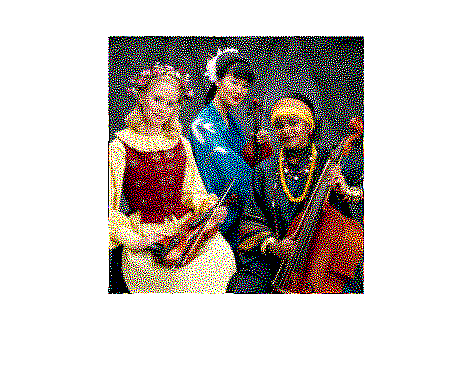

imshow(fargraster(image_m, 'imcdp'));

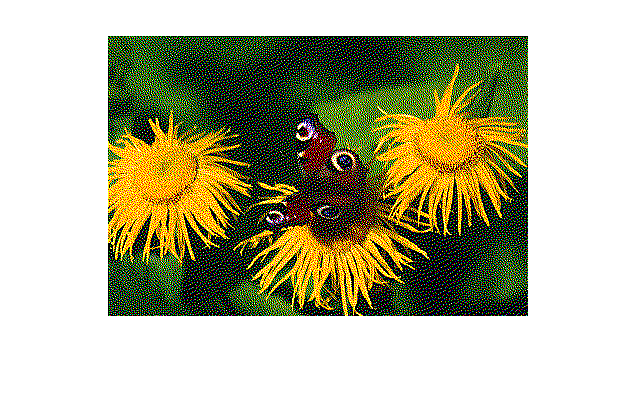


imshow(fargraster(image_b, 'errordif'));

imcdp
----------
23% done
----
47% done
----
here14
70% done
----
here14
here12
here13
94% done
----
here16
here11
here9
here5
here7
here15
here8
here18
here2
here4
here6
here17
here3
here10
here1
imcdp
----------
here14
24% done
----
here16
48% done
----
here14
here13
72% done
----
72% done
----
here12
here11
96% done
----
here10
here9
here6
here8
here7
here4
here5
here3
here18
here2
here17
here1
here15
imcdp
----------
here15
here16
here17
here3
here18
here2
here4
here14
88% done
----
here9
here7
here8
here6
here14
here10
here13
here11
here12
here5
here1


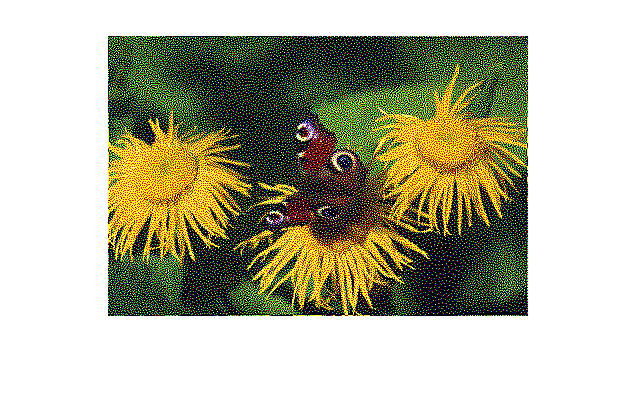

imshow(fargraster(image_b, 'imcdp'));


fargraster(image_m, 'hej');

No valid metod used
